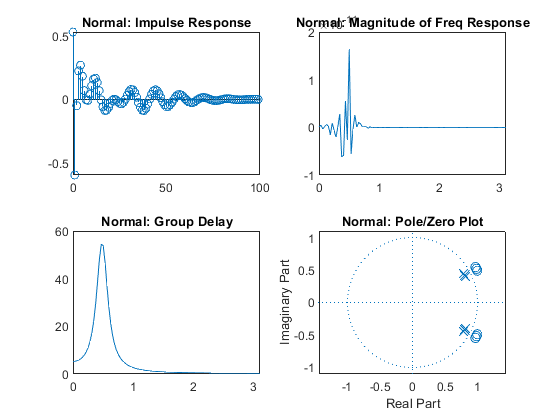

clear; load('projIA.mat');

soundsc(speech, fs); % Given sound sample output
pause(3);

Plots(b,a,0,'Normal', 1);
soundsc(filter(b,a,speech), fs); %Sounds very similar to original with no distortion
pause(3);

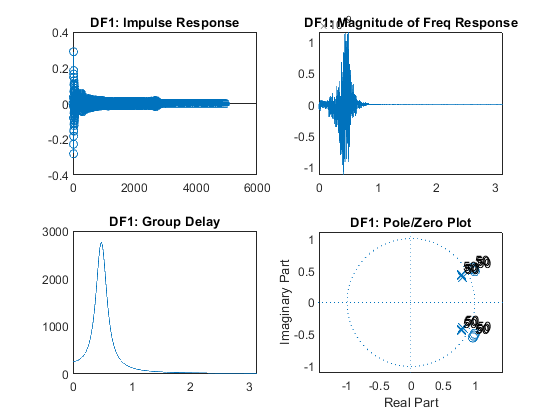


DF1 = dfilt.cascade(repmat(dfilt.df1(b,a),1,50));
Plots(b,a, DF1,'DF1', 0);
soundsc(filter(DF1, speech), fs); % Sounds as if there's a reverb of a high freq noise in the background
pause(3);

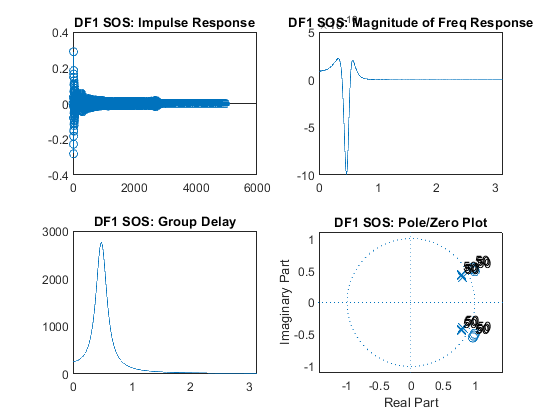


DF1_SOS = dfilt.cascade(repmat(sos(dfilt.df1(b,a)), 1, 50));
Plots(b,a,DF1_SOS,'DF1 SOS', 0);
soundsc(filter(DF1_SOS, speech), fs); % Sounds as if there's a reverb of a high freq noise in the background
pause(3);

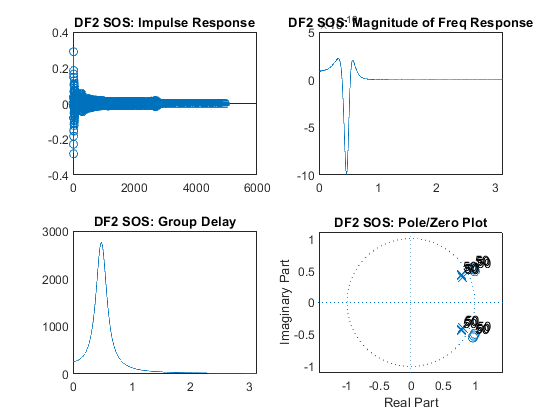


DF2_SOS = dfilt.cascade(repmat(sos(dfilt.df2(b,a)),1,50)); 
Plots(b,a, DF2_SOS,'DF2 SOS', 0); 
soundsc(filter(DF2_SOS, speech), fs); % Sounds as if there's a reverb of a high freq noise in the background
pause(3);

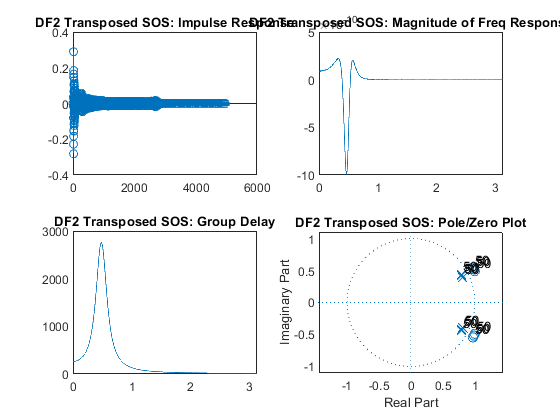


DF2_Trans_SOS = dfilt.cascade(repmat(dfilt.df2tsos(tf2sos(b,a)), 1, 50));
Plots(b,a,DF2_Trans_SOS,"DF2 Transposed SOS",0); 

soundsc(filter(DF2_Trans_SOS, speech), fs); % Sounds as if there's a reverb of a high freq noise in the background

## Comments

% This project is meant to test the trade-offs between filter classes. This
% was done by using the dfilt function with differnt direct forms and
% plotting their impulse responses, frequency magnitudes, Group delays, and
% pole/zero plots. the speech signal was then put through each filter and
% the output sound was compared to the original. What was found was that
% the filter with N = 1 sounded almsot identical to original, while all teh
% others sounded as if there was a reverb of a high freq noise in the
% background.

function Plots(b,a,filt,Title,first)
    if(first) % frist filter
        [H,T] =impz(b,a,100);
        [h,w] = freqz(b,a, 100);
        [gd,W] = grpdelay(b,a,100);
        zeros = roots(b);
        poles = roots(a);     
    else % all other filters 
        [H,T] =impz(filt, 5000);
        [h,w] = freqz(filt, 5000);
        [gd,W] = grpdelay(filt);
        [zeros,poles] = filt.zpk; 
    end
    
    figure();
    subplot(2,2,1);
    stem(T,H)
    title(Title + ": Impulse Response");
    
    subplot(2,2,2);    
    plot(w, 10*log10(abs(h)));
    title(Title + ": Magnitude of Freq Response");
    
    subplot(2,2,3);
    plot(W, gd);
    title(Title + ": Group Delay");
    
    subplot(2,2,4);
    zplane(zeros,poles);
    title(Title + ": Pole/Zero Plot");
end